## SMOTE for Time-series Imbalanced Classification Data.

**- Problem **: Unbalance Data.

**- Goal** : Getting the balanced data set for classification.

**- Method** : Over sampling, Under sampling, Under Over Pipeline Sampling, SMOTE

**- Metrics** : F1, accuracy, p-values, correlation, precision

## STEP of implementation

1. Prepare imbalance dataset

    1. Normal

    2. Unbalance data set

2. Load Function (or write by your own)

    1. Over sampler

    2. Under sampler

    3. UOP

    4. SMOTE

3. Load Machine learning model.

    1. Multi ML that provided in MATLAB

4. Create Testing data set

    1. Majority data set

    2. Minority data set

5. Testing the function with Testing data set

    1. Over

    2. Under

    3. UOP

    4. SMOTE

6. Performance Monitoring

    1. F1, accuracy, p-values, correlation, precision

7. Visualize the testing data set

8. Testing with the real data set “Normal and Unbalance” data set

9. Report Summary.

## Prepare imbalance data set.

clear
cd '/Volumes/490FILES/DataScience/Unbalance Motor/dataset/mat'
% load '/'

## Load Function

addpath '/Users/sitt_490/Documents/MATLAB_Extention/SMOTE/SMOTE'
addpath '/Users/sitt_490/Documents/MATLAB_Extention/SEMBlance/semblance'

## Load Data Set

clear
data.files = []; data.labels = []; data.targets = [];
final.files = []; final.labels = []; final.targets = [];

load 'single/dataset_normal_600.mat'
data.files{end+1} = split_dataset_input;
data.labels{end+1} = repmat("normal",300,1);
data.targets{end+1} = split_dataset_response;

load 'single/dataset_unbalance_600.mat'
data.files{end+1} = split_dataset_input;
data.labels{end+1} = repmat("unbalance",length(data.files{end}),1);
data.targets{end+1} = split_dataset_response;

final = data

final = struct with fields:
      files: {[300×200 double]  [900×200 double]}
     labels: {[300×1 string]  [900×1 string]}
    targets: {[300×5 int32]  [900×5 int32]}


data.labels{1}(1)

ans = "normal"

data.targets{1}(1,:)

ans = 1×5 int32 row vector
   1   0   0   0   0


## Visualize Data

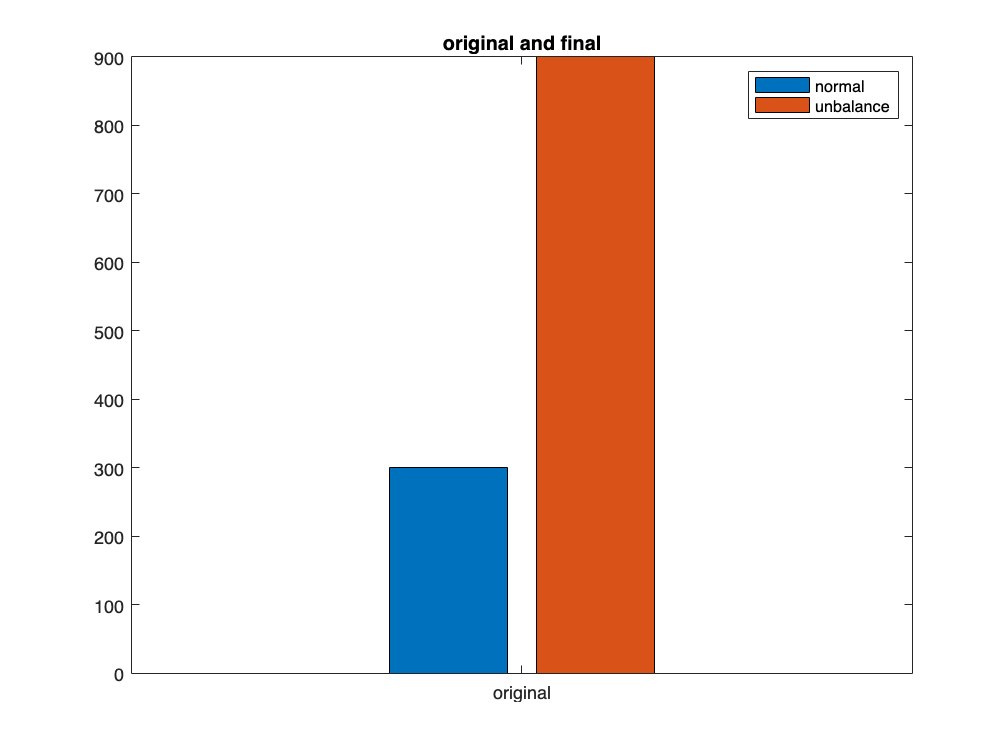

figure
X = categorical({'original'});
X = reordercats(X,{'original'});
Y = [...
    sum(data.labels{1} == "normal"), sum(data.labels{2} == "unbalance")...
    ];
bar(X,Y)
title('original and final')
legend (["normal","unbalance"])

## ML with Original Data Set

X = vertcat(data.files{:})

X = 1.0e-03 *

    0.2649    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0010    0.0006    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3754    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0018    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

y = vertcat(data.targets{:})

y = 1200×5 int32 matrix
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0


nprtool

ML_original.Network

ans =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2032
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

ML_original.TrainingResults

ans = struct with fields:
        trainFcn: 'trainscg'
      trainParam: [1×1 struct]
      performFcn: 'crossentropy'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1 2 3 5 9 10 11 14 16 19 20 21 22 23 24 26 27 28 29 30 31 33 34 35 37 39 40 41 44 45 47 48 49 52 53 56 62 65 66 67 69 70 71 72 73 74 75 77 78 80 82 85 86 88 89 90 93 95 96 98 99 101 102 104 105 106 107 108 111 114 117 119 120 121 … ]
          valInd: [6 15 36 43 50 54 57 58 59 60 63 83 84 91 92 97 103 112 118 126 131 134 136 143 150 161 163 168 175 199 201 208 216 218 229 233 238 244 255 257 262 267 275 277 280 284 296 297 306 308 309 310 312 318 326 331 336 341 359 369 375 385 … ]
         testInd: [4 7 8 12 13 17 18 25 32 38 42 46 51 55 61 64 68 76 79 81 87 94 100 109 110 113 115 116 127 130 135 142 149 154 157 165 169 172 174 179 183 187 188 190 191 192 193 202 203 211 217 219 227 239 242 250 252

## Makeup the Imbalance Data Set

Let makeup that data set is having normal to unbalance ratio = 100:1

data.files{2} = data.files{2}(1:length(data.files{1})*.01,:);
data.labels{2} = data.labels{2}(1:length(data.files{1})*.01,:);
data.targets{2} = data.targets{2}(1:length(data.files{1})*.01,:)

data = struct with fields:
      files: {[300×200 double]  [3×200 double]}
     labels: {[300×1 string]  [3×1 string]}
    targets: {[300×5 int32]  [3×5 int32]}


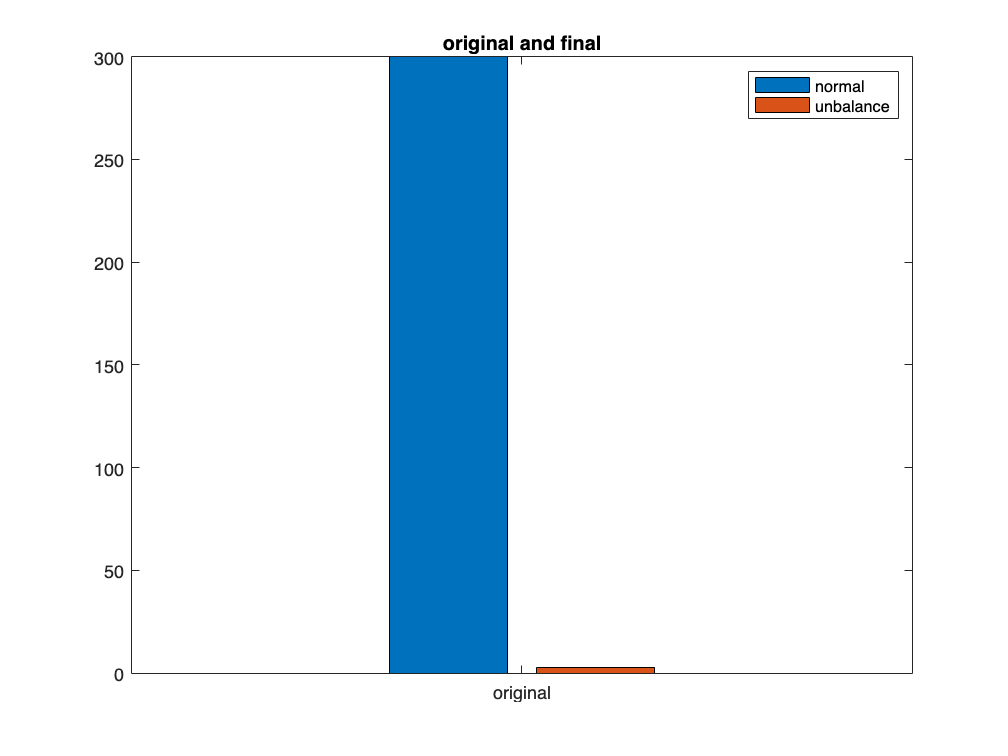

figure
X = categorical({'original'});
X = reordercats(X,{'original'});
Y = [...
    sum(data.labels{1} == "normal"), sum(data.labels{2} == "unbalance")...
    ];
bar(X,Y)
title('original and final')
legend (["normal","unbalance"])

X = vertcat(data.files{:})

X = 1.0e-03 *

    0.2649    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0010    0.0006    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3754    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0018    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

y = vertcat(data.targets{:})

y = 303×5 int32 matrix
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0


nprtool

ML_makeup.Network

ans =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2032
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

ML_makeup.TrainingResults

ans = struct with fields:
        trainFcn: 'trainscg'
      trainParam: [1×1 struct]
      performFcn: 'crossentropy'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1 2 3 5 6 9 10 11 12 13 14 15 16 20 21 22 23 24 26 29 30 31 34 35 42 43 44 45 47 48 51 52 53 54 55 57 58 60 67 68 70 71 73 75 76 77 80 81 83 84 85 87 91 92 93 96 97 98 99 101 102 103 106 108 112 113 115 116 117 118 120 121 123 124 … ]
          valInd: [8 28 38 40 46 49 61 62 69 74 82 88 114 119 126 127 131 132 134 136 138 142 144 153 157 173 176 188 190 193 196 222 224 228 234 237 258 263 266 270 275 278 280 300 301]
         testInd: [4 7 17 18 19 25 27 32 33 36 37 39 41 50 56 59 63 64 65 66 72 78 79 86 89 90 94 95 100 104 105 107 109 110 111 122 140 141 152 161 166 171 177 191 197 201 206 207 214 229 230 235 243 248 251 252 254 255 271 282 292]
            stop: 'Training finished: Reached minimum

## Method - Under Sampler (terminate majority)

final = data

final = struct with fields:
      files: {[300×200 double]  [3×200 double]}
     labels: {[300×1 string]  [3×1 string]}
    targets: {[300×5 int32]  [3×5 int32]}


minsize = min(cellfun('size',data.files,1))

minsize = 3

sel_idx = randi(length(data.labels{1}),minsize,1)

sel_idx =    137
   275
   237


final.files{1} = data.files{1}(sel_idx,:);
final.labels{1} = data.labels{1}(sel_idx,:);
final.targets{1} = data.targets{1}(sel_idx,:)

final = struct with fields:
      files: {[3×200 double]  [3×200 double]}
     labels: {[3×1 string]  [3×1 string]}
    targets: {[3×5 int32]  [3×5 int32]}


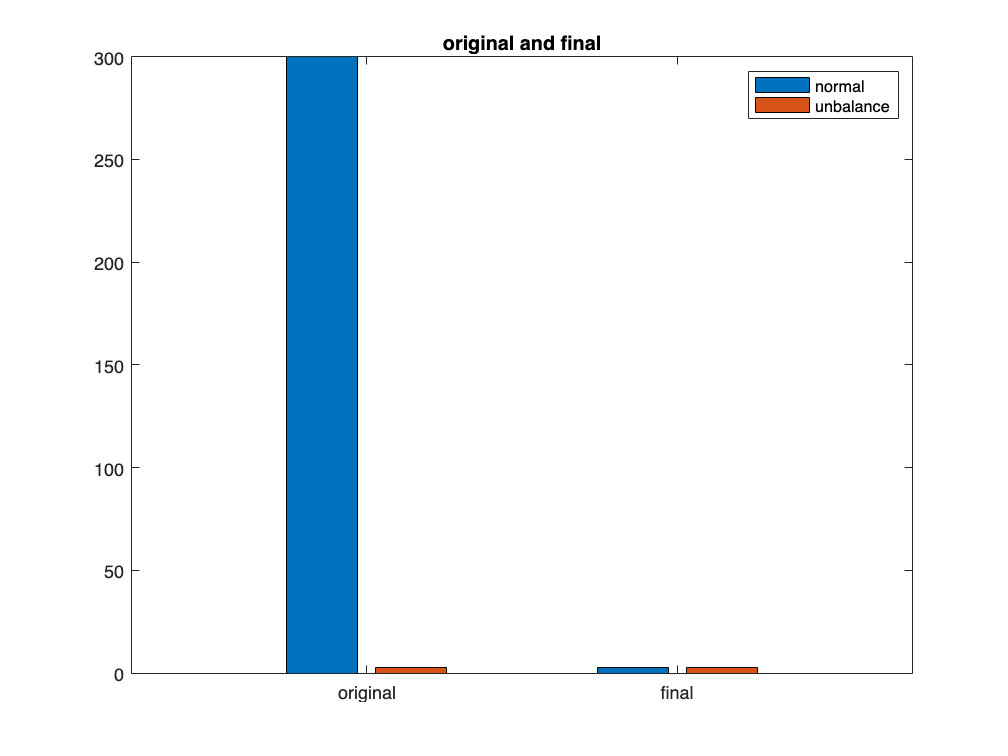

figure
X = categorical({'original','final'});
X = reordercats(X,{'original','final'});
Y = [...
    [sum(data.labels{1} == "normal"), sum(data.labels{2} == "unbalance")];...
    [sum(final.labels{1} == "normal"), sum(final.labels{2} == "unbalance")];...
    ];
bar(X,Y)
title('original and final')
legend (["normal","unbalance"])

X = vertcat(final.files{:})

X = 1.0e-03 *

    0.3754    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0018    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3754    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0018    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

y = vertcat(final.targets{:})

y = 6×5 int32 matrix
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   0   1   0   0   0
   0   1   0   0   0
   0   1   0   0   0


% nprtool cannot training due to low number of data set

## Method - Over Sampler (dupliacte minority)

final = data

final = struct with fields:
      files: {[300×200 double]  [3×200 double]}
     labels: {[300×1 string]  [3×1 string]}
    targets: {[300×5 int32]  [3×5 int32]}


maxsize = max(cellfun('size',data.files,1))

maxsize = 300

sel_idx = randi(length(data.labels{2}),maxsize,1)

sel_idx =      1
     1
     3
     3
     1
     2
     3
     1
     2
     2


final.files{2} = data.files{2}(sel_idx,:);
final.labels{2} = data.labels{2}(sel_idx,:);
final.targets{2} = data.targets{2}(sel_idx,:)

final = struct with fields:
      files: {[300×200 double]  [300×200 double]}
     labels: {[300×1 string]  [300×1 string]}
    targets: {[300×5 int32]  [300×5 int32]}


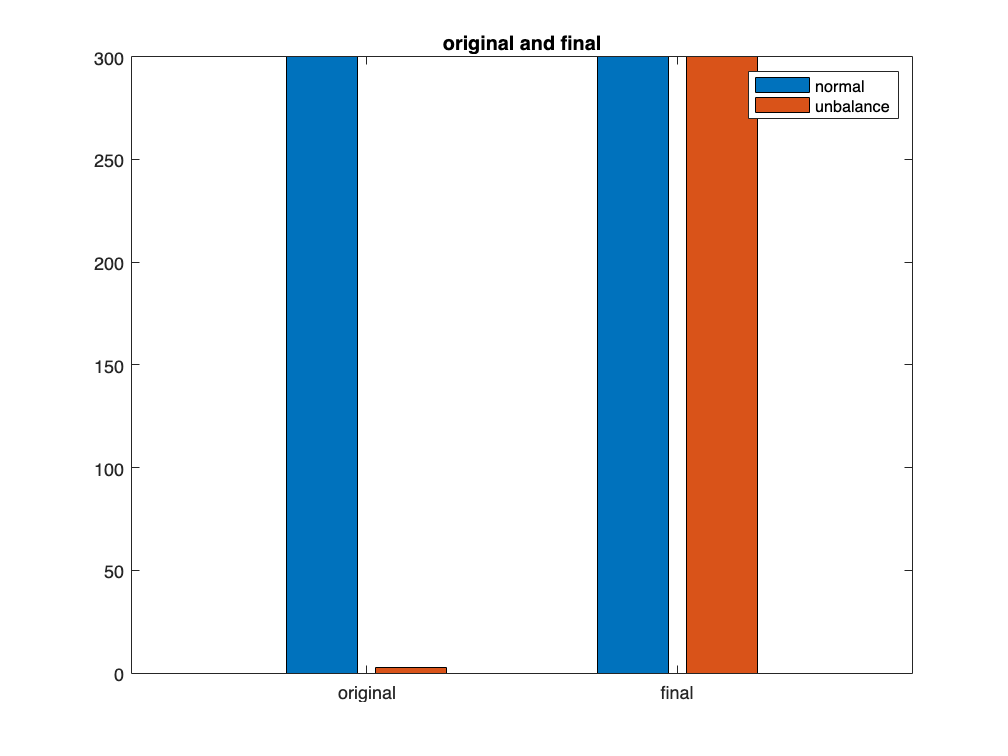

figure
X = categorical({'original','final'});
X = reordercats(X,{'original','final'});
Y = [...
    [sum(data.labels{1} == "normal"), sum(data.labels{2} == "unbalance")];...
    [sum(final.labels{1} == "normal"), sum(final.labels{2} == "unbalance")];...
    ];
bar(X,Y)
title('original and final')
legend (["normal","unbalance"])

X = vertcat(final.files{:})

X = 1.0e-03 *

    0.2649    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0010    0.0006    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3754    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0018    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

y = vertcat(final.targets{:})

y = 600×5 int32 matrix
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0


nprtool

ML_oversampling.Network

ans =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2032
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

ML_oversampling.TrainingResults

ans = struct with fields:
        trainFcn: 'trainscg'
      trainParam: [1×1 struct]
      performFcn: 'crossentropy'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1 2 3 5 8 9 11 12 14 15 16 18 19 20 21 22 23 24 25 26 27 29 30 32 33 35 36 38 39 40 41 42 43 44 46 47 48 52 53 54 55 58 60 61 62 63 64 66 67 68 69 70 71 72 73 74 75 77 79 80 82 83 85 88 92 93 97 98 101 102 103 107 108 109 110 112 … ]
          valInd: [4 7 28 34 37 49 56 59 84 86 91 94 95 99 100 105 111 122 127 139 141 142 150 151 152 166 173 174 186 191 199 200 204 209 211 212 214 218 219 220 221 223 229 230 232 240 248 259 262 275 285 286 288 290 294 299 300 312 319 321 322 337 … ]
         testInd: [6 10 13 17 31 45 50 51 57 65 76 78 81 87 89 90 96 104 106 114 117 126 131 140 149 157 158 162 167 185 188 195 196 202 203 207 225 227 228 235 236 249 250 252 256 257 269 274 278 279 281 282 289 295 305

## Method - Pipeline

- OverSampling the minority class to have 10% of #majority class.

- UnderSampling the majority class to have 50% of #majority class.

final = data

final = struct with fields:
      files: {[300×200 double]  [3×200 double]}
     labels: {[300×1 string]  [3×1 string]}
    targets: {[300×5 int32]  [3×5 int32]}


% over sampling - duplicate the minority to be 50% of majority (about 30 rand sel)"
sel_idx = randi(length(data.labels{2}),maxsize*.5 ,1)

sel_idx =      3
     2
     2
     1
     1
     1
     2
     3
     2
     1


final.files{2} = data.files{2}(sel_idx,:);
final.labels{2} = data.labels{2}(sel_idx,:);
final.targets{2} = data.targets{2}(sel_idx,:)

final = struct with fields:
      files: {[300×200 double]  [150×200 double]}
     labels: {[300×1 string]  [150×1 string]}
    targets: {[300×5 int32]  [150×5 int32]}


% under sampling - terminate the majority to be state that have 60% minority"
minsize = min(cellfun('size',final.files,1))

minsize = 150

sel_idx = randi(length(data.labels{1}),minsize/.6,1)

sel_idx =     60
   235
    40
   103
    95
   264
   165
    18
   244
   198


final.files{1} = data.files{1}(sel_idx,:);
final.labels{1} = data.labels{1}(sel_idx,:);
final.targets{1} = data.targets{1}(sel_idx,:)

final = struct with fields:
      files: {[250×200 double]  [150×200 double]}
     labels: {[250×1 string]  [150×1 string]}
    targets: {[250×5 int32]  [150×5 int32]}


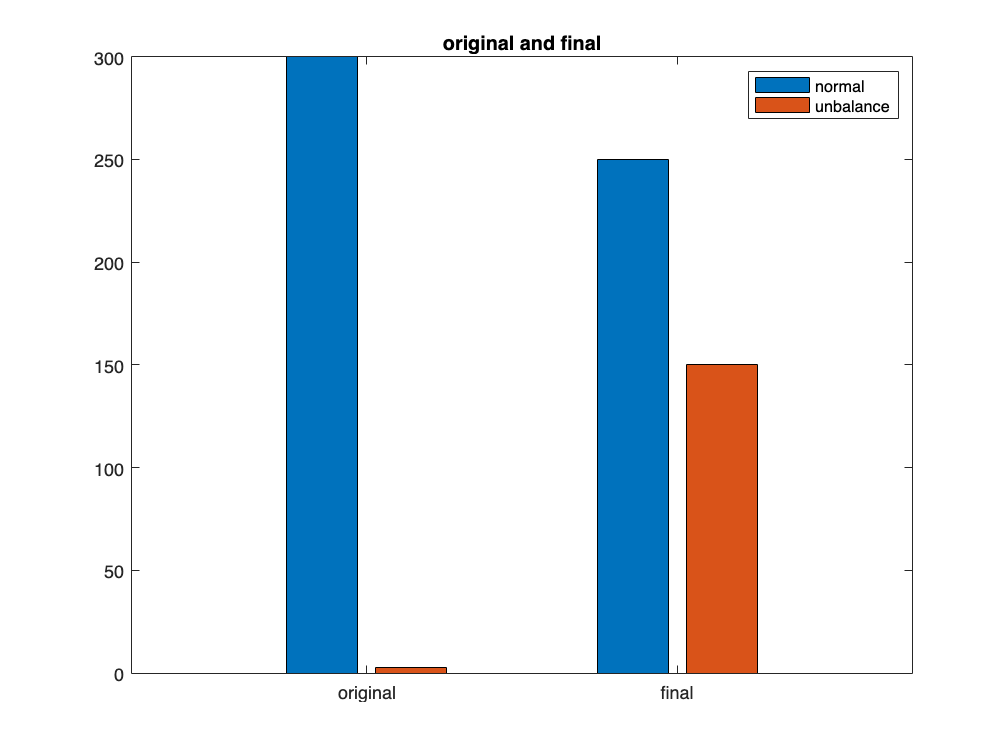

figure
X = categorical({'original','final'});
X = reordercats(X,{'original','final'});
Y = [...
    [sum(data.labels{1} == "normal"), sum(data.labels{2} == "unbalance")];...
    [sum(final.labels{1} == "normal"), sum(final.labels{2} == "unbalance")];...
    ];
bar(X,Y)
title('original and final')
legend (["normal","unbalance"])

X = vertcat(final.files{:})

X = 1.0e-03 *

    0.2018    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0011    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2649    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0010    0.0006    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    

y = vertcat(final.targets{:})

y = 400×5 int32 matrix
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0
   1   0   0   0   0


nprtool

ML_pipeline.Network

ans =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2032
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

ML_pipeline.TrainingResults

ans = struct with fields:
        trainFcn: 'trainscg'
      trainParam: [1×1 struct]
      performFcn: 'crossentropy'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [3 4 6 7 10 12 14 15 21 22 23 26 28 29 30 31 32 33 34 36 38 39 40 48 49 51 54 55 58 60 61 62 63 64 65 66 67 68 69 70 71 73 74 76 77 80 81 82 85 87 89 90 91 94 95 96 97 98 99 100 101 104 105 106 107 108 110 111 115 117 118 121 122 … ]
          valInd: [1 5 9 11 13 16 17 18 24 35 37 42 45 47 50 52 53 72 78 79 84 92 93 109 112 119 124 131 132 137 140 153 155 159 177 215 216 217 222 256 282 288 291 293 294 314 322 327 333 335 340 346 349 351 355 368 373 377 383 389]
         testInd: [2 8 19 20 25 27 41 43 44 46 56 57 59 75 83 86 88 102 103 113 114 116 120 128 130 134 136 147 150 156 161 163 170 171 176 178 182 184 186 190 192 194 199 201 210 221 236 238 246 250 251 255 263 264 283 286 289 292 303 305 30

## Performance Monitoring.

## Visualize output of testing data set with synthesized data.

## Perform with Practical data set.

## Report Summary.

function files = randReplicateFiles(files,numDesired)
n = numel(files);
ind = randi(n,numDesired,1);
files = files(ind);
end